# Projektiranje sustava upravljanja brzinom vrtnje DC motora korištenjem diskretnog  postupka postavljanja polova (RST)

Istosmjerni (DC) motor opisan je linearnim modelom drugog reda oblika:


$$G_p(s)=\frac{K}{(1+T_1s)(1+T_2s)}$$


pri čemu je $K=10$, $T_1=5ms$ i $T_2=30ms$. Potrebno je projektirati diskretni TG regulator kako bi se postiglo vladanje prema prototipnom Butterworthovom obliku uz $t_m=10ms$:

tm=10e-3;
K=10;
T1=5e-3;
T2=30e-3;
Gp=tf(K,conv([T1 1],[T2 1])) %Proces

Gp =
 
             10
  -------------------------
  0.00015 s^2 + 0.035 s + 1
 
Continuous-time transfer function.



Proces se za potrebe projektiranja regulatora diskretnim RST postupkom diskretizira primjenom ZOH diskretizacije:


$$Gp(z)=(1-z^{-1})\mathcal{Z}\left\{\frac{G(s)}{s}\right\}$$


Td=0.003;
Gpd=c2d(Gp,Td,'zoh')%Diskretizirani proces

Gpd =
 
    0.2396 z + 0.1898
  ----------------------
  z^2 - 1.454 z + 0.4966
 
Sample time: 0.003 seconds
Discrete-time transfer function.



Ad=Gpd.Denominator{1};
Bd=Gpd.Numerator{1};
n=2;

Diskretna prijenosna funkcija procesa jedanaka je:


$$G_{pd}(z)=\frac{ 0.1146 z + 0.09806}{  z^2 - 1.606 z + 0.6271}

$$


## Projektiranje diskretnog RST regulatora

Kako je proces reda n=2 tada redovi polinoma RST regulatora iznose:


$$\deg{R}=\deg{S}=\deg{T}=\deg{A_o}=n-1=1$$


 Polinom $A_m(z)$je istog reda kao i proces tj. drugog reda i određujemo ka preslikavanjem polova odgovarajućeg kontinuiranog ponoma na temelju odziva prototipnog Butterworthovog vladanja 2. reda.

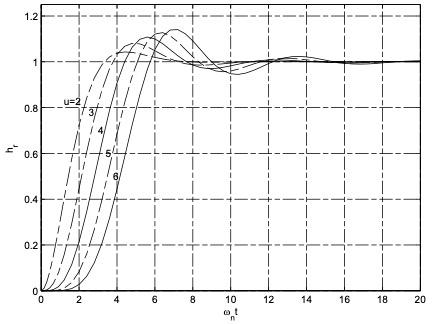 

Iz grafa se može očitati da se vrijeme prvog maksimuma za sustav drugog reda postiže za $\omega_n t_m=4.3$ odakle slijedi da je prirodna frekvencija neprigušenih oscilacija jednaka $\omega_n$ jednaka:

omg0=4.3/tm

omg0 = 430

Prema tome polovi željenog vladanja zatvorenog regulacijskog kruga (u kontinuiranom području) definirani su polinomom


$$A_m(s)=s^2+1.4\omega_n s+\omega_n^2$$


Am=[1 1.4*omg0 omg0^2];
Gm=tf(omg0^2,Am);
[hc,tc]=step(Gm,0.04);
p=roots(Am)

p = 	1.0e+02 *

  -3.0100 + 3.0708i
  -3.0100 - 3.0708i


z=exp(p*Td)

z =    0.2452 + 0.3228i
   0.2452 - 0.3228i


Amz=poly(z)

Amz =     1.0000   -0.4903    0.1643


Bmz=Gpd.Numerator{1};%Bm(z)=B(z)
Ao=[1 0];
Ac=conv(Amz,Ao);

Sljedeči korak je formiranje sustava jednadžbi:

H=[[rot90(Ad);0] [0;rot90(Ad)] [rot90(Bd);0] [0;rot90(Bd)]]

H =     0.4966         0    0.1898         0
   -1.4536    0.4966    0.2396    0.1898
    1.0000   -1.4536         0    0.2396
         0    1.0000         0         0


G=[rot90(Ac)];
X=H\G

X =     0.3813
    1.0000
   -0.9977
    2.4293


Rješenje sustava jednadžbi su polinomi $R(z)$ i $S(z)$.

R=flipud(X(1:n))'

R =     1.0000    0.3813


S=flipud(X(n+1:end))'

S =     2.4293   -0.9977


T=sum(Ac)/sum(Bd)*Ao; %T(z)=Ac(1)/B(1)*Ao(z)

## Simulacija vladanja sustava

Prijenosna funkcija zatvorenog regulacijskog kruga:

Gzd=tf(conv(Bd,T),conv(Ad,R)+conv(Bd,S),Td);

Simulacija sustava na skokovitu referentnu veličinu:

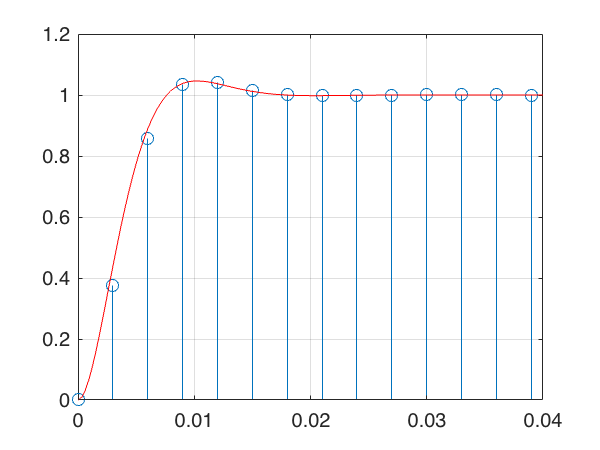

[h,t]=step(Gzd,0.04);
stem(t,h), grid on; hold on
plot(tc,hc,'r');